addpath Function\
addpath Template_data\ 

# ** Copy your code here:**


% One-side:  0.95  1-0.05
% Two-side:  u2u("95s")  u2u("5a")
conf=confidence_tool();

[sig1,sig2,e1,e2]=deal(0.0015,0.0015,34,34);
[mean1,s1,f1]=deal(0.0015,u2u("0.39mgon"),20);
[mean2,s2,f2]=deal(0.0015,u2u("0.27mgon"),15);

[a,b]=conf.get_interval_f(u2u("10a"),s1,s2,f1,f2);

The interval boundary is [0.9468,2.144]
The confidence Level = 90.00%, Error probability = 10.00%


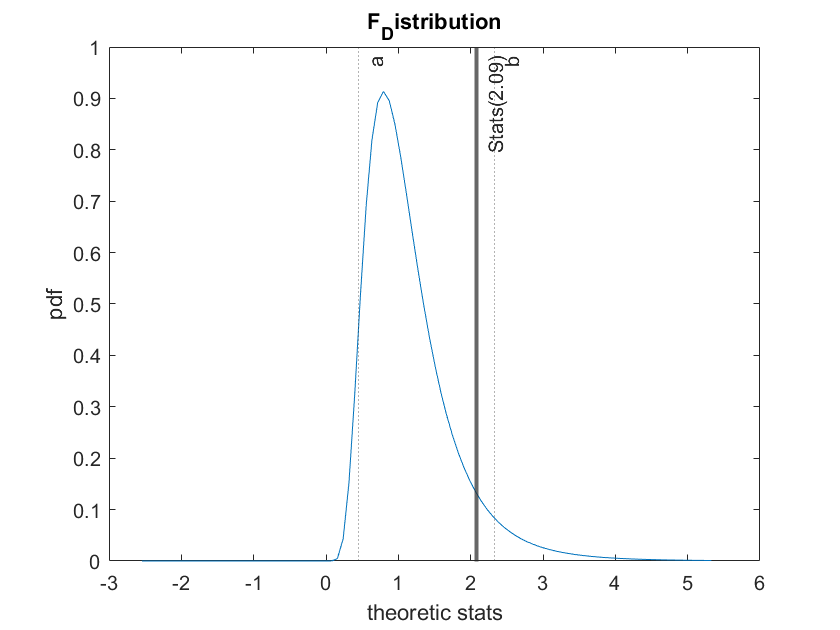

Test Statistic (s2/s1)^2: 2.09 ,Critical value=[0.45,2.33]
Fails to reject the null hypothesis H0


stats=conf.statistic_test_f(u2u("10a"),sig1,sig2,s1,s2,f1,f2);

# **Note:**

**One Side Problem:**

a=5 s=95 in lecture 

0.95 in matlab function

u2u("10a) u2u("90s) in my code

**Two Side Problem:**

a=5 s=95 in lecture 

0.975 in matlab function

u2u("5a) u2u("95s) in my code